创建一个4×4×5的数据组

A = zeros(4,4,5);
A(:,:,1) = xlsread("统计表1.xlsx",'10','B2:E5');
A(:,:,2) = xlsread("统计表1.xlsx",'18','B2:E5');
A(:,:,3) = xlsread("统计表1.xlsx",'25','B2:E5');
A(:,:,4) = xlsread("统计表1.xlsx",'30','B2:E5');
A(:,:,5) = xlsread("统计表1.xlsx",'35','B2:E5');

利用上述数据创立Y与X矩阵

Y = reshape(A,4*4*5,1);             %生长率
X = [ones(4*4*5,1) zeros(4*4*5,3)]; %影响因素的观测值
index = [12	19	25	32    0;
         0.02   0.08    0.3     1.6   0;
         10     18      25      30    35];
for k=1:5
    for j=1:4
        for i=1:4
            X((k-1)*4*4+(j-1)*4+i,2) = index(1,j);  %温度
            X((k-1)*4*4+(j-1)*4+i,3) = index(2,i);  %光强(*10e-16)
            X((k-1)*4*4+(j-1)*4+i,4) = index(3,k);  %盐度
        end
    end
end

标准化，统一变量量纲

温度:°c

盐度无量纲

光强应统一为lx，但是对比发现数据有误，故不转化（下面是转化后的）

Ys = (mapstd(Y'))';     
X3pro = 132.89.*X(:,3);
Xs = [X(:,1:2) X3pro X(:,4)];

选定模型，计算回归系数

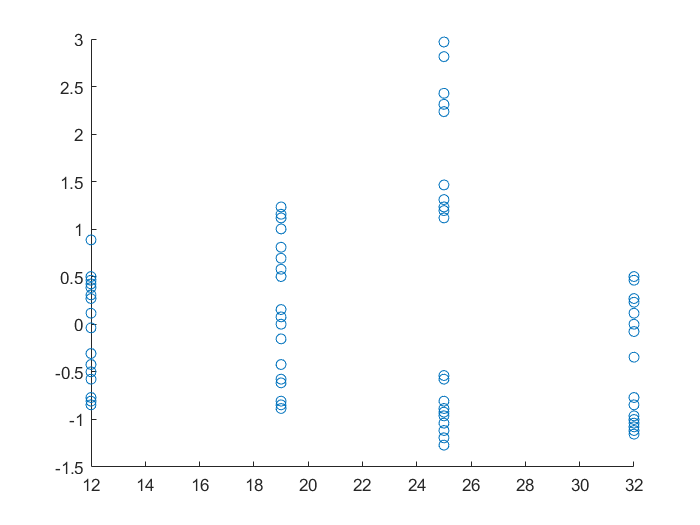

scatter(Xs(:,2),Ys);

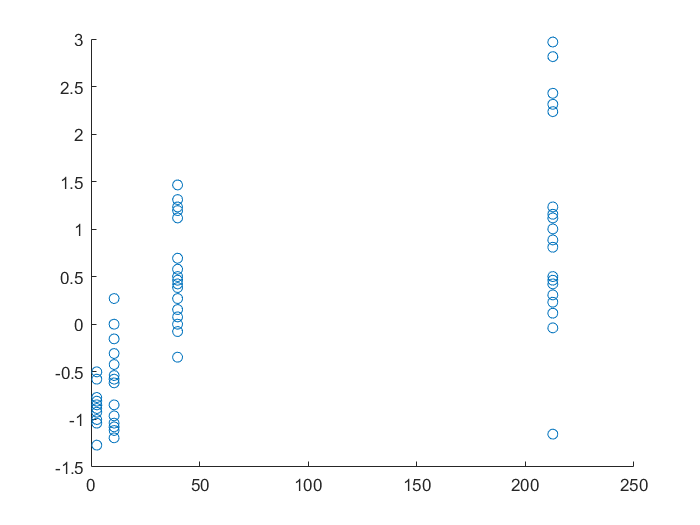

scatter(Xs(:,3),Ys);

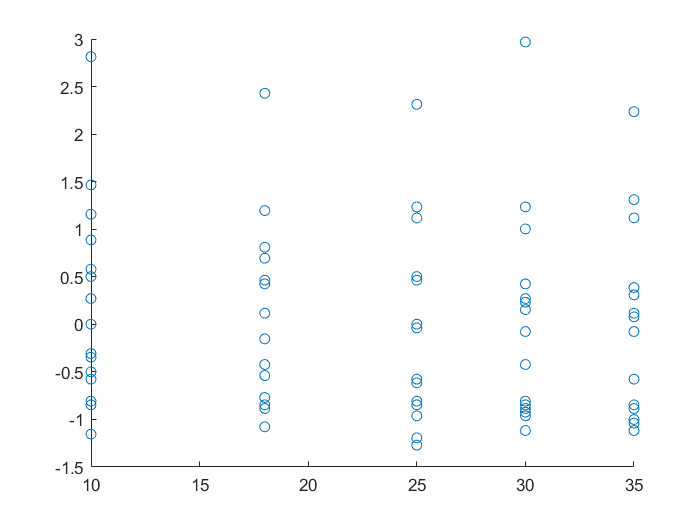

scatter(Xs(:,4),Ys);

模型一


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 X_2 +\beta_3 X_3 +u$$


[b1,bint1,~,~,stats1] = regress(Ys,Xs);
b1

b1 =    -0.1321
   -0.0059
    0.0076
   -0.0104


bint1

bint1 =    -0.8442    0.5800
   -0.0289    0.0170
    0.0057    0.0096
   -0.0296    0.0088


stats1

stats1 =     0.4423   20.0893    0.0000    0.5797


这里拟合效果不好

模型二


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 {\textrm{lnX}}_2 +\beta_3 X_3 +u$$


%对数据处理，把非线性模型转化为线性模型 
X3_modle2 = log(Xs(:,3));
Xc1 = [Xs(:,1) Xs(:,2) X3_modle2 X(:,4)];
[b2,bint2,~,~,stats2] = regress(Ys,Xc1);
b2

b2 =    -1.0554
   -0.0059
    0.4620
   -0.0104


bint2

bint2 =    -1.7266   -0.3842
   -0.0259    0.0141
    0.3709    0.5531
   -0.0271    0.0063


stats2

stats2 =     0.5775   34.6343    0.0000    0.4391


这里拟合效果不好

模型三


$$Y=\beta_0 +\beta_1 X_1 +\beta_2 {\textrm{lnX}}_2 +\beta_3 {X_1 X}_3 +\beta_4 {X_2 X}_3 +u$$


X3_modle3 = log(Xs(:,3));
X4_modle3 = X(:,2).*X(:,4);
X5_modle3 = X(:,3).*X(:,4);
Xc2 = [Xs(:,1) Xs(:,2) X3_modle3 X4_modle3 X5_modle3];
[b3,bint3,~,~,stats3] = regress(Ys,Xc2);
b3

b3 =    -1.2682
    0.0039
    0.4429
   -0.0004
    0.0023


bint3

bint3 =    -1.8615   -0.6750
   -0.0237    0.0315
    0.2792    0.6065
   -0.0012    0.0004
   -0.0140    0.0186


stats3

stats3 =     0.5753   25.3992    0.0000    0.4473


这里拟合效果不好

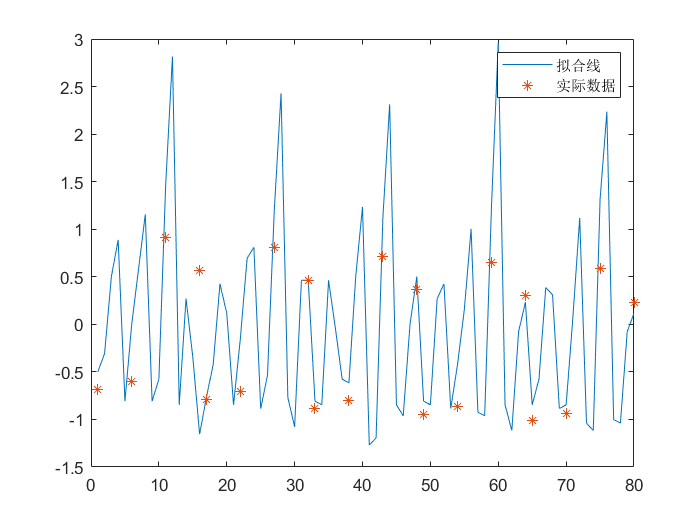

index = [1 6 11 16 17 22 27 32 33 38 43 48 49 54 59 64 65 70 75 80];
x = 1:80;
y = [-0.499508492532222
-0.306834049896843
0.5023986091717531
0.887747494442513
-0.80778760074883
0.0014450583197654
0.579468386225905
1.15749171413205
-0.80778760074883
-0.576578269586375
1.46577082234865
2.81449192079631
-0.846322489275906
0.271189278009297
-0.345368938423919
-1.15460159749251
-0.769252712221754
-0.42243871547807
0.425328832117601
0.117049723900993
-0.846322489275906
-0.152694495788539
0.695073051807133
0.810677717388361
-0.884857377802982
-0.5380433810592991
1.19602660265912
2.42914303552555
-0.769252712221754
-1.07753182043836
0.463863720644677
0.463863720644677
-0.80778760074883
-0.846322489275906
0.463863720644677
-0.03708983020731061
-0.576578269586375
-0.615113158113451
0.5023986091717531
1.2345614911862
-1.27020626307374
-1.19313648601959
1.11895682560497
2.31353836994432
-0.846322489275906
-0.961927154857134
0.0014450583197654
0.5023986091717531
-0.80778760074883
-0.846322489275906
0.271189278009297
0.425328832117601
-0.884857377802982
-0.42243871547807
0.155584612428069
1.00335216002374
-0.923392266330058
-0.961927154857134
1.2345614911862
2.96863147490462
-0.846322489275906
-1.11606670896544
-0.0756247187343866
0.232654389482221
-0.846322489275906
-0.576578269586375
0.386793943590525
0.309724166536373
-0.884857377802982
-0.846322489275906
0.0785148353739174
1.11895682560497
-1.03899693191129
-1.11606670896544
1.31163126824035
2.23646859289017
-1.00046204338421
-1.03899693191129
-0.0756247187343866
0.117049723900993
];
yf = [-0.6814671639952083
-0.6341295112070389
0.4465721470798599
0.5650910260932526
-0.6732859868797129
-0.6014048027450575
0.7215529177638364
1.21958519533288
-0.6545049987850094
-0.5262808503662434
0.912742106353331
2.722064242909162
-0.6814671639952083
-0.6341295112070389
0.1448200376429987
0.5650910260932526
-0.787368800091202
-0.7400311473030325
0.3406705109838662
0.4591893899972588
-0.7791876229757066
-0.7073064388410513
0.6156512816678425
1.113683559236886
-0.760406634881003
-0.6321824864622371
0.8068404702573372
2.616162606813168
-0.787368800091202
-0.7400311473030325
0.03891840154700493
0.4591893899972588
-0.8800327316751966
-0.8326950788870271
0.2480065793998716
0.3665254584132643
-0.8718515545597013
-0.7999703704250459
0.522987350083848
1.021019627652892
-0.8530705664649976
-0.7248464180462318
0.7141765386733428
2.523498675229174
-0.8800327316751966
-0.8326950788870271
-0.05374553003698962
0.3665254584132643
-0.9462212542351926
-0.8988836014470231
0.1818180568398756
0.3003369358532682
-0.9380400771196973
-0.8661588929850419
0.456798827523852
0.9548311050928958
-0.9192590890249936
-0.7910349406062278
0.6479880161133466
2.457310152669178
-0.9462212542351926
-0.8988836014470231
-0.1199340525969857
0.3003369358532682
-1.012409776795189
-0.9650721240070193
0.1156295342798795
0.2341484132932721
-1.004228599679693
-0.932347415545038
0.3906103049638559
0.8886425825328996
-0.9854476115849898
-0.8572234631662239
0.5817994935533506
2.391121630109182
-1.012409776795189
-0.9650721240070193
-0.1861225751569818
0.2341484132932721];
plot(x,y);
hold on
plot(x(index),yf(index),'*');
legend('拟合线','实际数据');
hold off

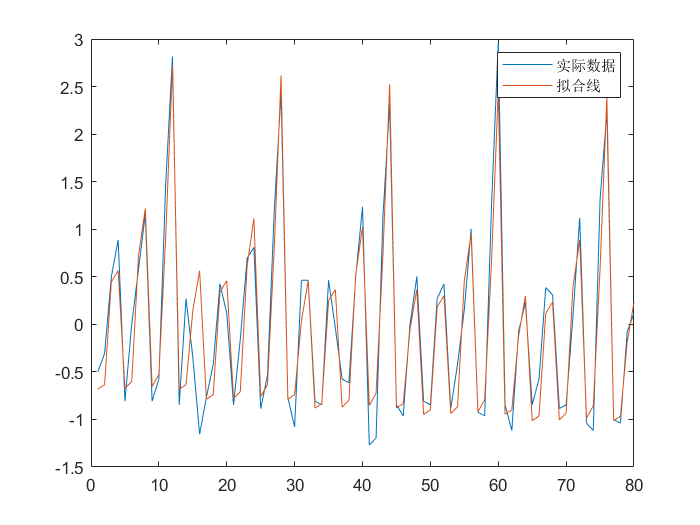

plot(x,y,x,yf);
legend('实际数据','拟合线');